clear
load('/Users/danicaroth/Documents/Academic/Analysis/Nonlocal/RockDropData/final_XR.mat','Xfinal','Rfinal','CensorPoint');
dir='/Users/danicaroth/Documents/Academic/Analysis/Nonlocal/TopographicData/';
site={'H20c-avgz' 'N39c-avgz'};%H17c-avgz
iorder=[2 4 6 1 3 5 7]; %reorder colors from figure order from plot_rockdst_disentrainmentrate_FINAL.m
colors=[237 177 32; 179 177 32; 119 172 48; 119 172 48; 77 190 238; 0 131 205; 126 47 142]./255;%colors for plotting hi-pass
colors=colors(iorder,:);
theta=0.1;
CensorPoint=cell2mat(CensorPoint(iorder,:)); %final censor points used for each site and rock size, based on both slope breaks and tail data that overly biases lomax fit (e.g., due to collection of clasts at roots)
cp=max(CensorPoint([2 7],:)-theta,[],2);
slopedeg=[20 39];
slope=tan(deg2rad(slopedeg));
yt=[150;304];%transect number (manually selected for each site)
filtsigma =1*100; %gaussian filter sigma (in m) (converted to nelements or cm)
hsize =1*100; %gaussian filter window size (converted to nelements or cm)
titletext={'Burned (S=0.36)' 'Vegetated (S=0.81)'};
for i=1:2
    file=[dir,site{i},'-1cm-bgplaneN.tif'];
    Nraster{i}=imread(file)';
    [Nraster_lp{i},Nraster_hp{i}] = nangaussfilt(Nraster{i},hsize,filtsigma,'plot','off');
    nx=size(Nraster{i},2); ny=size(Nraster{i},1);
    y{i} = [1:ny]./100;
    y{i}=y{i}-y{i}(yt(i))+2;
    x{i} = ([1:nx]./100);
    z{i} = Nraster{i}(yt(i),:);
    x{i} = x{i}./cosd(slopedeg(i))-theta; %convert x to along-ground reference frame (matching travel distances) and shift by truncation distance (theta)
end
fig=figure;clf

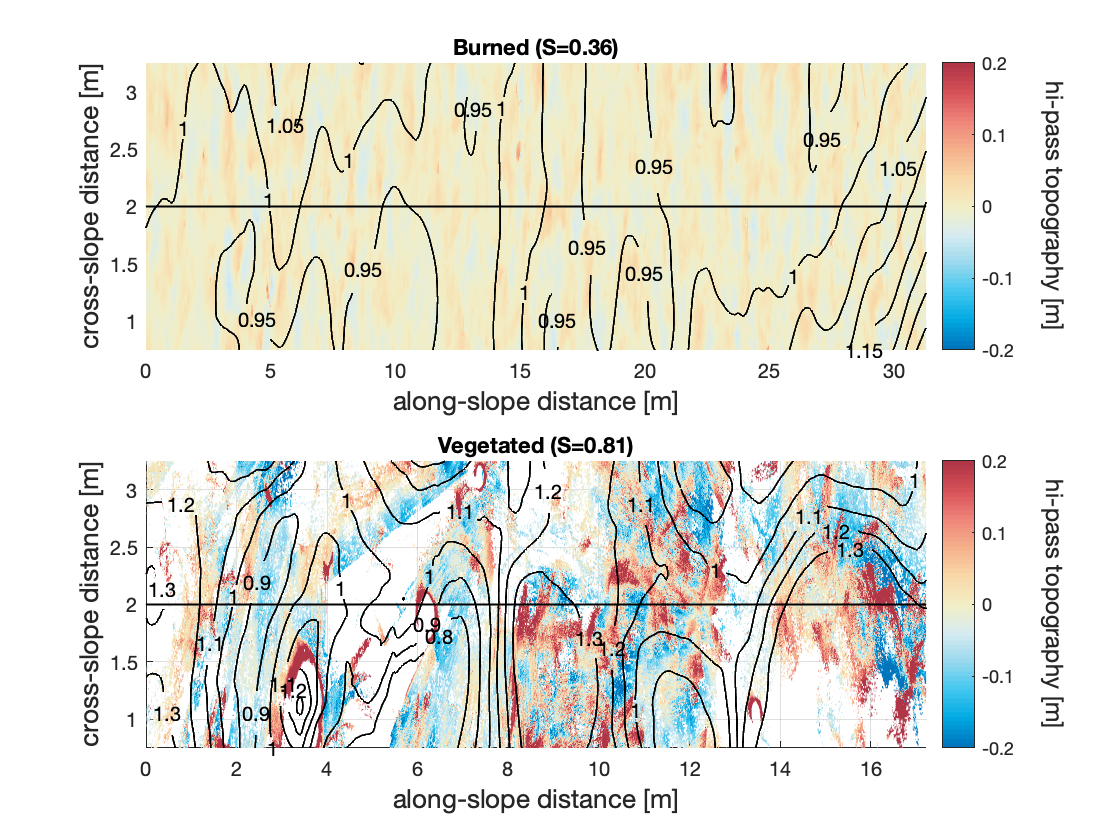

clims =0.2.*[-1 1];
%Contours originally: -0.15:0.05:0.25
contours{1} =[-0.1:0.05:0.3];
contours{2} =[-0.2:0.1:0.3];
for i=1:2
    figure(fig);
    s(i)=subplot(2,1,i);
    [h{i},a{i},c{i},C{i}] = contsurfoverlay(Nraster_hp{i},Nraster_lp{i},'contours',contours{i},'titletext',titletext(i),'offset',1,'dx',0.01,'dy',0.01);
    clabel(C{i},c{i});
    caxis(clims);
    xlim([0 1.05*cp(i)])
    ylim([y{i}(yt(i))-1.25 y{i}(yt(i))+1.25])
%     Pos0{i}=get(gca,'Position');
    
    l(i)=line([x{i}(1) x{i}(end)], [y{i}(yt(i)) y{i}(yt(i))],'Parent',s(i));
    set(l(i),'Color','k','linewidth',1,'ZData',max(Nraster_hp{i},[],'all')*[1 1]+10);
    
    xlabel('along-slope distance [m]','fontsize',13)
    ylabel('cross-slope distance [m]','fontsize',13)
    
    col=colorbar;
    
    % set(col,'Position',get(col,'Position')+[0.05*Pos0{1}(3) 0 0 0]);
    set(get(col,'Label'),'string','hi-pass topography [m]','Interpreter','tex','fontsize',12,'rotation',-90,'Position',get(get(col,'Label'),'Position')+[1.5 0 0]);

end

pause(5);%pause that's weirdly needed or positioning gets screwed up (maybe due to next process running before values are updated??
% yl=get(s(1),'YLabel');
% set(yl,'string','along-slope distance (m)','fontsize',13,'position',get(yl,'position')+[-10 0 0]);

pause(5); %pause that's weirdly needed or positioning gets screwed up (maybe due to next process running before values are updated??

col=colorbar;

% set(col,'Position',get(col,'Position')+[0.05*Pos0{1}(3) 0 0 0]);
set(get(col,'Label'),'string','hi-pass topography [m]','Interpreter','tex','fontsize',12,'rotation',-90,'Position',get(get(col,'Label'),'Position')+[1.5 0 0]);


% pos = [0 1051 638 984];
% set(gcf,'position',pos);

% % LABELING CONTOURS CORRECTLY MUST BE DONE IN ILLUSTRATOR: 
% % MANUALLY DELETE CONTOURS, SAVE SURFACE AS LOWER-RES PDF (below),
% % UNDO DELETE, DELETE SURFACE MANUALLY, SAVE CONTOURS AS OPENGL EPS (below)
% print('-dpdf','-r1000','/Users/danicaroth/Documents/Academic/NSF Postdoc/Rock Drops/figures/forpaper/SurfaceRoughnerss.pdf')
% print('-depsc2','-openGL','/Users/danicaroth/Documents/Academic/NSF Postdoc/Rock Drops/figures/forpaper/SurfaceContours.eps')
